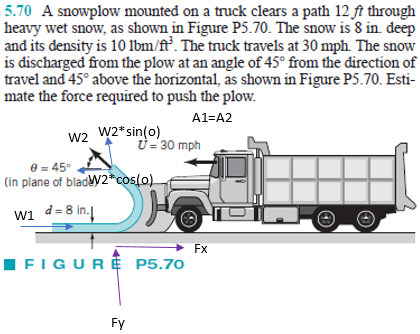

# given

u = symunit;
rho = 10*u.lbm/u.ft^3;
w = 12*u.ft;
d = 8*u.in;
Vcv = 30*u.mph;
theta = 45*u.deg;

# inflow properties

A1 = rewrite(w*d, u.ft);
V1 = 0;
W1 = abs(V1-(-Vcv));
W1x = W1;
W1y = 0;
mdot1 = rewrite(rho*A1*W1, 'US');

# outflow properties

A2 = A1;
W2 = W1;
W2x = W2*cos(theta);
W2y = W2*sin(theta);
mdot2 = rewrite(rho*A2*W2, 'US');

# conservation of momentum (x-direction)

Fx = -mdot1*(W1x)+mdot2*(-W2x);
Fx = simplify(rewrite(Fx, u.lbf));
Fx_vpa = vpa(Fx, 6) %#ok

$$Fx\_vpa = -8217.7\,\mathrm{lbf}$$

clear Fx_vpa;

# conservation of momentum (y-direction)

Fy = -mdot1*(W1y)+mdot2*(W2y);
Fy = simplify(rewrite(Fy, u.lbf));
Fy_vpa = vpa(Fy, 6) %#ok

$$Fy\_vpa = 3403.88\,\mathrm{lbf}$$

clear Fy_vpa;